## Boyle—Mariotteův zákon

 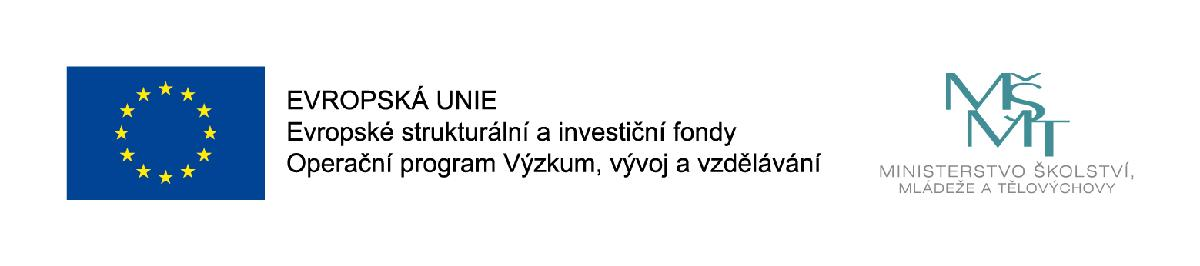

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

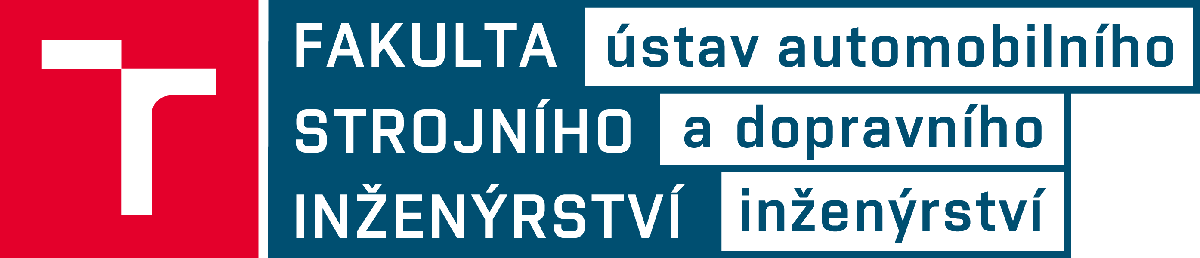

Boyle (1662), Mariotte (1672) sledovali chování plynu za konstantní teploty. 

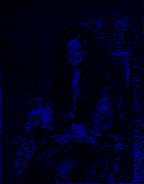                                                      

**Slovní formulace: **

Za konstantní teploty je součin tlaku a objemu daného množství plynu konstantní.

**Matematická formulace:**


$$\[pV = konst.\; \Rightarrow \;{p_1}{V_1} = {p_2}{V_2}\]$$


**Zákon lze vyjádřit i pomocí stlačitelnosti **

$\[V = {V_o}\left[ {1 + \delta  \cdot (p - p{}_o{\kern 1pt} )} \right]\]$                    [m^3]

Stlačitelnosti *d *není však ani u ideálních plynů konstantní, a proto uvedená závislost *V = f(p)* není přímka.

Při prvních pokusech, které byly prováděny s plyny, bylo zjišťováno, jak se mění tlak plynu změnou jeho objemu při konstantní teplotě*. *Pokus provedl r. 1662 *Boyle* (1627—1691) a r. 1679 opakoval *Mariotte* (1620—1684). Mě­řením bylo zjištěno, že změna tlaku je při téže teplotě obráceně úměrná změně objemu.

Tuto závislost označujeme jako *zákon **Boyleův**—**Mariotteův*

V diagramu o souřadnicích *p, v *je tento zákon 

### Výkreslení Boyle—Mariotteův zákona pro různé měrné objemy v nádobě

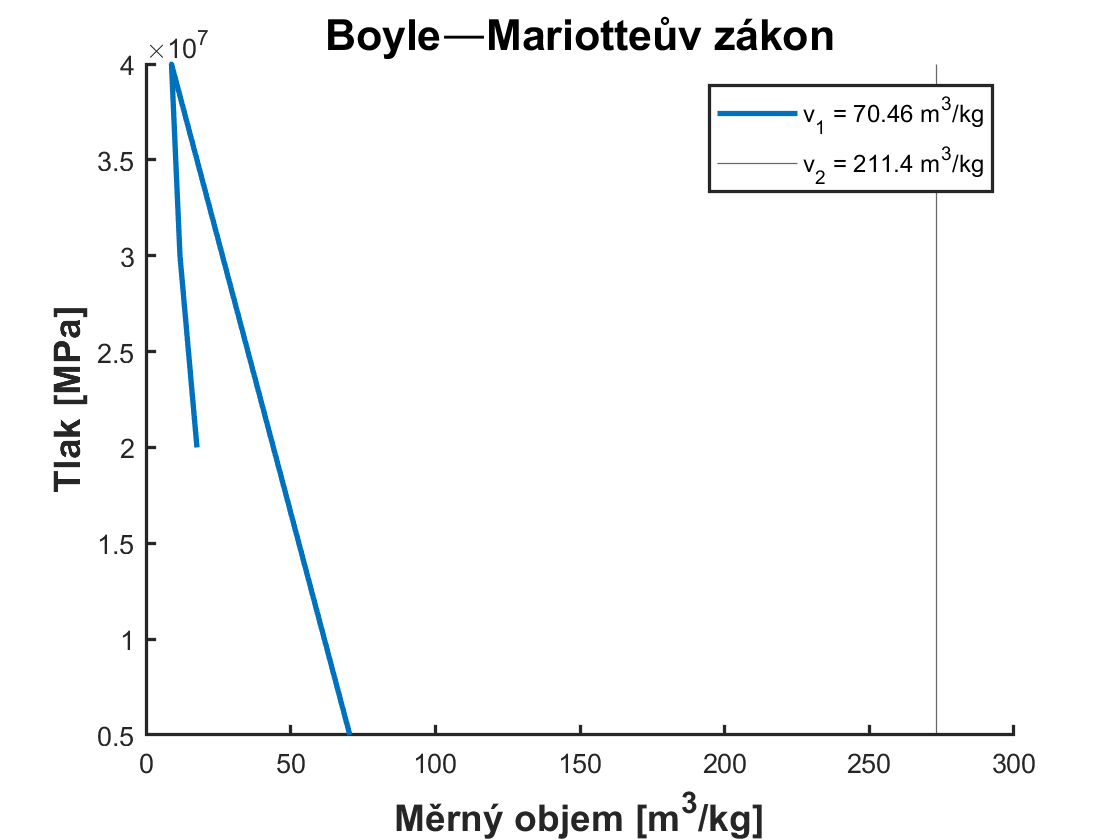

clear,clc,close all;
figure;
r = 259.8;     % Měrná plynová konstanta pro kyslík
p0_1 = MPa2Pa(5.0);
T0 = 273.15;
v0_1 = p0_1/(r*T0);
p(1) = p0_1;
V(1) = v0_1;
p(2) = 4.0*MPa;
V(2) = p(1)*V(1)/p(2);
p(3) = 3.0*MPa;
V(3) = p(2)*V(2)/p(3);
p(4) = 2.0*MPa;
V(4) = p(3)*V(3)/p(4);
hold on;
plot(V,p,'-','linewidth',2);
p0_2 = 1.5*MPa;
T0 = 273.15;
v0_2 = p0_2/(r*T0);
T(1) = 0;
p(1) = p0_2/T0*T(1)/MPa;
T(2) = 263.15;
p(2) = p0_2/T0*T(2)/MPa;
T(3) = 373.15;
p(3) = p0_2/T0*T(3)/MPa;
T(4) = 473.15;
p(4) = p0_2/T0*T(4)/MPa;
%plot(T,p,'-','linewidth',2);
p0_3 = 2.0*MPa;
T0 = 273.15;
v0_3 = p0_3/(r*T0);
T(1) = 0;
p(1) = p0_3/T0*T(1)/MPa;
T(2) = 263.15;
p(2) = p0_3/T0*T(2)/MPa;
T(3) = 373.15;
p(3) = p0_3/T0*T(3)/MPa;
T(4) = 473.15;
p(4) = p0_3/T0*T(4)/MPa;
%plot(T,p,'-','linewidth',2);
hold off;
title('Boyle—Mariotteův zákon','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Měrný objem [m^3/kg]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Tlak [MPa]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
%xlim([1 15]);
%ylim([0 1]);
%grid on;
set(gca, 'linewidth',1.2);
xline(273.15);
legend(['v_1 = ' num2str(v0_1,4) ' m^3/kg'],['v_2 = ' num2str(v0_2,4) ' m^3/kg'],['v_3 = ' num2str(v0_3,4) ' m^3/kg'],'0 °C')

#### Výkreslení Charlesova zákona pro různé plyny v nádobě

figure;


### Příklad

Monopost formule 1 optimálně pracuje, pokud má teplotu pneumatik 92 °C a tlak 240 kPa. Na jaký tlak musí mechanik pneumatiky nahustit, pokud v době huštění mají pneumatiky teplotu 22 °C. Atmosférický tlak v době huštění je 1010 hPa, kdežto při závodě se předpokládá atmosferický tlak 990 hPa.

Doplňujicí otázky:

Závisí huštení na objemu pneumatiky?

Má na to vliv druh plynu?

to = 92.0;          % °C
po = kPa2Pa(240);       % kPa
th = 22.0;            % °C
pbh = hPa2Pa(1010);   % hPa
pbo = hPa2Pa(990);    % hPa

Absolutní teploty a tlaky

To = C2K(to);
Th = C2K(th);
poa = po + pbo;

Výpočet

pha = poa*Th/To;
ph = pha - pbh;
fprintf('Tlak na, který je třeba hustit je  %.3f kPa\n',Pa2kPa(ph));

Tlak na, který je třeba hustit je  173.013 kPa


Výsledný tlak je nezávislý na velikosti pneumatiky a plynu, kterým byla nahuštěna.

# Funkce

% Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   
% Převádí teplotu ve stupních Celsia na Kelvíny
function [K] = C2K(C)
K = C+273.15;
end
% Převádí hektopascaly na Pascaly
function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 
% Převádí hektopascaly na Pascaly
function [Pa] = MPa2Pa(MPa)
Pa = MPa*10^6;
end 
% Převádí hektopascaly na Pascaly
function [Pa] = kPa2Pa(kPa)
Pa = kPa*10^3;
end 
% Převod litrů
function [m3] = l2m3(l)
m3 = l*.001;
end
% Převod litrů
function [l] = m32l(m3)
l = m3 /0.001;
end
% Převod Pascalů
function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end
% Převod Watů
function [kW] = W2kW(W)
kW = W/1000;
end
% Převod
function [mm] = m2mm(m)
mm = m*1000;
end
% Převod
function [m] = mm2m(mm)
m = mm / 1000;
end
% Převod
function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end
%Převod 
function [res] = MPa
    res = 10000000.0;
end
%Převod 
function [bar] = Pa2bar(Pa)
    bar = Pa/100000;
end
% Převod jednotek pressure from bar to pascals.
function [Pa] = bar2Pa(bar)
    Pa = bar*100000;
end
% Převod jednotek temperature from Kelvin to degrees Celsius.
function [C] = K2C(K)
    C = K-273.15;
end